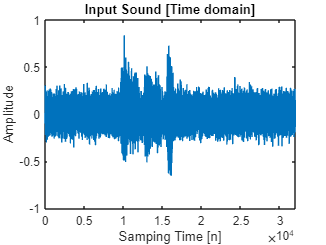

load('sec1-speech.mat');
autoplot(xM, "Input Sound [Time domain]", ...
    "Samping Time [n]", "Amplitude")

% Variable Prepare
LEN = length(xM);
H1 = dft(xM, LEN);
fn = fs / 2;
divide = LEN / fs;

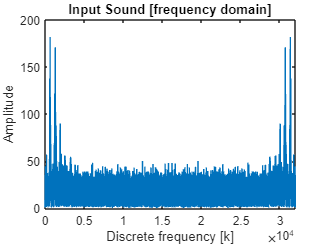

% Ploting Sound properties
autoplot(abs(H1), "Input Sound [frequency domain]", ...
    "Discrete frequency [k]", "Amplitude")

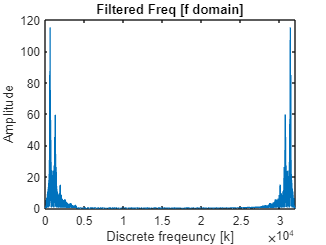

% Variable
LOW = 2 * pi * 150;
HIGH = 2 * pi * 240;
DAMP = 0.707;

% 2nd order BANDPASS
for k=1:LEN
    if k <= fn
        f = k / 4;
        w = 2 * pi * f;
    else
        f = (fn - (k / 4 - fn));
        w = 2 * pi * f;
    end
    H1(k) = H1(k) * low(w, HIGH, DAMP) * high(w, LOW, DAMP);
end
autoplot(abs(H1), "Filtered Freq [f domain]", ...
    "Discrete freqeuncy [k]", "Amplitude")

Y = idft(H1, LEN);

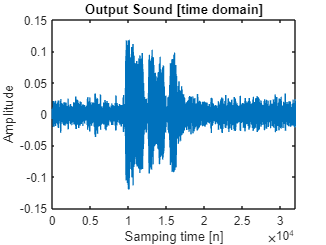

autoplot(Y, "Output Sound [time domain]", ...
        "Samping time [n]", "Amplitude")

sound(Y, fs)
mse = speechErr(Y, 1)

mse = 0.0033

% audiowrite("testet.wav", Y, fs)

function autoplot(PLOT, TITLE, XLABEL, YLABEL)
    plot(PLOT)
    title(TITLE)
    xlabel(XLABEL)
    ylabel(YLABEL)
end

% Discrete Fourier Transform
function Xf = dft(Xt, N)
    Xf = ones(N, 1) * 0;
    k = 0;
    while k < N
        n = 0;
        while n < N
            freq = 2 * pi * k * n / N;
            add = Xt(n + 1) * exp(-1i * freq);
            Xf(k + 1) = Xf(k + 1) + add;
            n = n + 1;
        end
        k = k + 1;
    end
end

% Inverse Discrete Fourier Transform
function Xt = idft(Xf, N)
    Xt = ones(N, 1) * 0;
    n = 0;
    while n < N
        k = 0;
        while k < N
            freq = 2 * pi * k * n / N;
            add = Xf(k + 1) * exp(1i * freq);
            Xt(n + 1) = Xt(n + 1) + real(add);
            k = k + 1;
        end
        Xt(n + 1) = Xt(n + 1) / N;
        n = n + 1;
    end
end

% Lowpass
function lp = low(w, cutoff, damp)
    s = 1i * w;
    MID = 2 * damp * cutoff * s;
    lp = cutoff .^ 2  / (s .^ 2 + MID + cutoff .^ 2);
end

% Highpass
function hp = high(w, cutoff, damp)
    s = 1i * w;
    MID = 2 * damp * cutoff * s;
    hp = s .^ 2 / (s .^ 2 + MID + cutoff .^ 2);
end

% Amplifier
